# EEP557 HW8

Qingchuan Hou

12/12/2022

clc

syms T_em T_shaft T_d theta_l omega_l theta_m omega_m theta_ast_l omega_ast_l s
syms K_lisa K_lsa b_la b_ra K_misa K_msa b_ma 
syms J_m J_l b_r K_r
syms T_ast_CFF omega_dot_ast J_hat_l

% Physical System Resonant Load
eq1 = theta_l == omega_l/s

$$eq1 = \theta_{l}=\frac{\omega_{l}}{s}$$

eq2 = omega_l == (1/(J_l*s)) * (T_shaft - T_d)

$$eq2 = \omega_{l}=-\frac{T_{d}-T_{\mathrm{shaft}}}{J_{l}\,s}$$

eq3 = T_shaft == (theta_m-theta_l) * K_r + (omega_m-omega_l) * b_r

$$eq3 = T_{\mathrm{shaft}}=-K_{r}\,\left(\theta_{l}-\theta_{m}\right)-b_{r}\,\left(\omega_{l}-\omega_{m}\right)$$

eq4 = theta_m == omega_m/s

$$eq4 = \theta_{m}=\frac{\omega_{m}}{s}$$

eq5 = omega_m == (1/(J_m*s)) * (T_em + (theta_l-theta_m) * K_r + (omega_l-omega_m) * b_r)

$$eq5 = \omega_{m}=\frac{T_{\mathrm{em}}+K_{r}\,\left(\theta_{l}-\theta_{m}\right)+b_{r}\,\left(\omega_{l}-\omega_{m}\right)}{J_{m}\,s}$$


eq6 = T_em == T_ast_CFF + (theta_ast_l-theta_l) * (K_lisa/s + K_lsa) + (omega_ast_l - omega_l)*b_la + (omega_l-omega_m)*b_ra 

$$eq6 = T_{\mathrm{em}}={T^{*}}_{\mathrm{CFF}}-\left(K_{\mathrm{lsa}}+\frac{K_{\mathrm{lisa}}}{s}\right)\,\left(\theta_{l}-{\theta^{*}}_{l}\right)-b_{\mathrm{la}}\,\left(\omega_{l}-{\omega^{*}}_{l}\right)+b_{\mathrm{ra}}\,\left(\omega_{l}-\omega_{m}\right)$$

eq7 = theta_ast_l == omega_ast_l/s

$$eq7 = {\theta^{*}}_{l}=\frac{{\omega^{*}}_{l}}{s}$$


eqs = [eq1,eq2,eq3,eq4,eq5,eq6,eq7];

J_m = 6e-3;  J_l = 2e-3;  b_r = 5e-3;  K_r = 5e+2; K_lisa = 200.81; K_lsa = 37.66; b_la = 0.97; b_ra=6.37;


## a) Frequency Response with Command Feedforward

S1_a = solve(eqs,[theta_l, T_em, T_shaft, omega_l, omega_ast_l, omega_m, theta_m]);

eq1_a = theta_l == collect(S1_a.theta_l, [theta_ast_l, T_ast_CFF, T_d])

$$eq1\_a = \begin{array}{l} \theta_{l}=\frac{K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+K_{r}\,b_{\mathrm{la}}\,s^{2}+K_{\mathrm{lsa}}\,b_{r}\,s^{2}+b_{\mathrm{la}}\,b_{r}\,s^{3}}{\sigma_{1}}\,{\theta^{*}}_{l}+\frac{b_{r}\,s^{2}+K_{r}\,s}{\sigma_{1}}\,{T^{*}}_{\mathrm{CFF}}+\left(-\frac{K_{r}\,s+J_{m}\,s^{3}+b_{r}\,s^{2}+b_{\mathrm{ra}}\,s^{2}}{\sigma_{1}}\right)\,T_{d}\\ \mathrm{where}\\ \sigma_{1}=K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+J_{l}\,b_{r}\,s^{4}+J_{l}\,b_{\mathrm{ra}}\,s^{4}+J_{m}\,b_{r}\,s^{4}+K_{r}\,b_{\mathrm{la}}\,s^{2}+K_{\mathrm{lsa}}\,b_{r}\,s^{2}+b_{\mathrm{la}}\,b_{r}\,s^{3} \end{array}$$


subs1_a = children(rhs(eq1_a));

% solve T_ast_CFF/theta_ast_l with theta_l/theta_ast_l = 1 and ignal T_d
EQ1_a = T_ast_CFF/theta_ast_l == collect((1 - subs1_a{1}/theta_ast_l) / (subs1_a{2}/T_ast_CFF),s)

$$EQ1\_a = \frac{{T^{*}}_{\mathrm{CFF}}}{{\theta^{*}}_{l}}=\frac{\left(J_{l}\,J_{m}\right)\,s^{4}+\left(J_{l}\,b_{r}+J_{l}\,b_{\mathrm{ra}}+J_{m}\,b_{r}\right)\,s^{3}+\left(J_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{2}}{b_{r}\,s+K_{r}}$$


% replace J_l with J_hat_l
eq2_a = subs(EQ1_a, 'J_l', 'J_hat_l')

$$eq2\_a = \frac{{T^{*}}_{\mathrm{CFF}}}{{\theta^{*}}_{l}}=\frac{{\hat{J}}_{l}\,J_{m}\,s^{4}+\left({\hat{J}}_{l}\,b_{r}+{\hat{J}}_{l}\,b_{\mathrm{ra}}+J_{m}\,b_{r}\right)\,s^{3}+\left({\hat{J}}_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{2}}{K_{r}+b_{r}\,s}$$


% transfer response with solved T_ast_CFF
EQ2_a = theta_l/theta_ast_l == collect(subs1_a{1}/theta_ast_l + (subs1_a{2}/T_ast_CFF)*rhs(eq2_a),s)

$$EQ2\_a = \begin{array}{l} \frac{\theta_{l}}{{\theta^{*}}_{l}}=\frac{\left({\hat{J}}_{l}\,J_{m}\right)\,s^{5}+\left({\hat{J}}_{l}\,b_{r}+{\hat{J}}_{l}\,b_{\mathrm{ra}}+J_{m}\,b_{r}\right)\,s^{4}+\left(b_{\mathrm{la}}\,b_{r}+{\hat{J}}_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{3}+\sigma_{1}+\sigma_{2}+K_{\mathrm{lisa}}\,K_{r}}{\left(J_{l}\,J_{m}\right)\,s^{5}+\left(J_{l}\,b_{r}+J_{l}\,b_{\mathrm{ra}}+J_{m}\,b_{r}\right)\,s^{4}+\left(b_{\mathrm{la}}\,b_{r}+J_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{3}+\sigma_{1}+\sigma_{2}+K_{\mathrm{lisa}}\,K_{r}}\\ \mathrm{where}\\ \sigma_{1}=\left(K_{r}\,b_{\mathrm{la}}+K_{\mathrm{lsa}}\,b_{r}\right)\,s^{2}\\ \sigma_{2}=\left(K_{\mathrm{lisa}}\,b_{r}+K_{\mathrm{lsa}}\,K_{r}\right)\,s \end{array}$$

EQ3_a = collect(subs(EQ2_a),s)

$$EQ3\_a = \frac{\theta_{l}}{{\theta^{*}}_{l}}=\frac{\left(3000\,{\hat{J}}_{l}\right)\,s^{5}+\left(3187500\,{\hat{J}}_{l}+15\right)\,s^{4}+\left(250000000\,{\hat{J}}_{l}+1502425\right)\,s^{3}+242594150\,s^{2}+9415502025\,s+50202500000}{6\,s^{5}+6390\,s^{4}+2002425\,s^{3}+242594150\,s^{2}+9415502025\,s+50202500000}$$

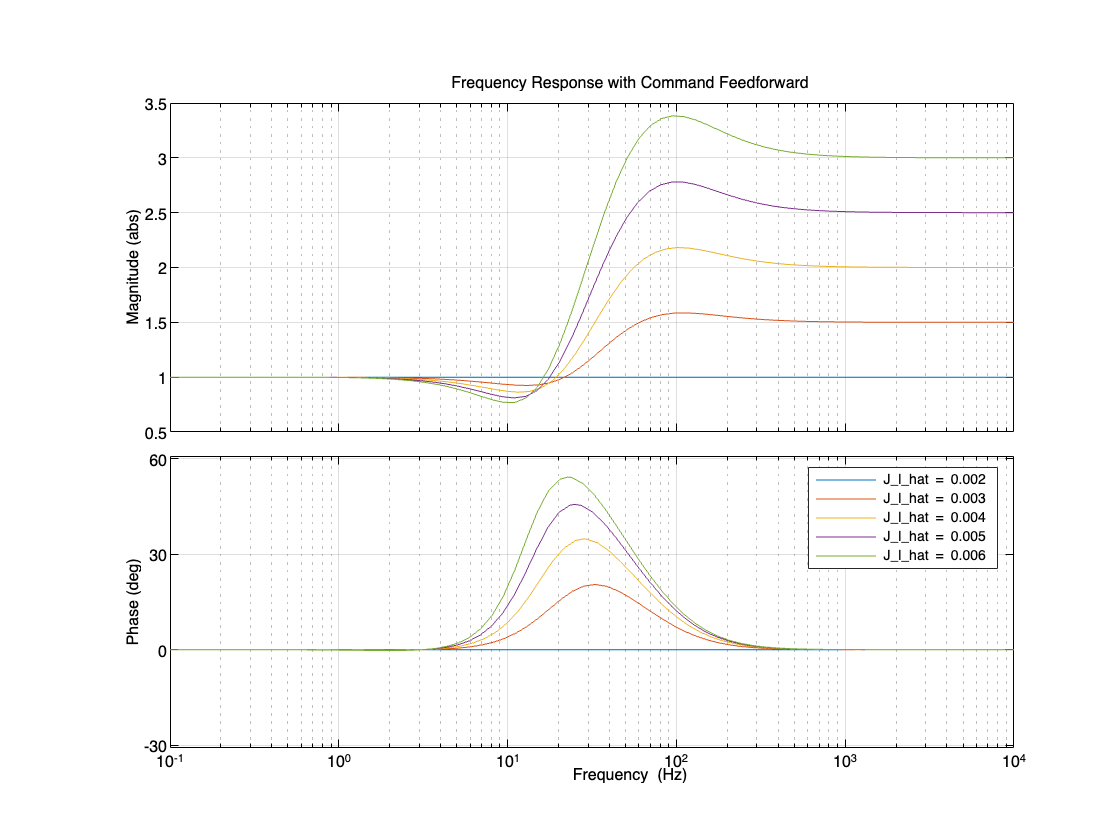


% TF plot with different J_l
opts = bodeoptions;
opts.MagUnits = 'abs';
opts.FreqUnits = 'Hz';
opts.Grid = 'on';
opts.XLimMode = 'manual';
opts.XLim = [0.1,1e+4];

n = 1;
tfs_a = {5};

figure
for x = linspace(2e-3, 6e-3, 5)
    EQ3_a_tf = subs(EQ3_a,J_hat_l,x);
    tfs_a{n} = syms2tf(simplify(rhs(EQ3_a_tf)));

    hold on;
    bodeplot(tfs_a{n},opts);
    n = n+1;
end
hold off;

legend('J_l_hat = 0.002','J_l_hat = 0.003','J_l_hat = 0.004','J_l_hat = 0.005','J_l_hat = 0.006')
title('Frequency Response with Command Feedforward')

## b) Frequency Response with Command Feedforward without Higher Oreder Commands

% when higher order derivatives are know:
EQ1_a

$$EQ1\_a = \frac{{T^{*}}_{\mathrm{CFF}}}{{\theta^{*}}_{l}}=\frac{\left(J_{l}\,J_{m}\right)\,s^{4}+\left(J_{l}\,b_{r}+J_{l}\,b_{\mathrm{ra}}+J_{m}\,b_{r}\right)\,s^{3}+\left(J_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{2}}{b_{r}\,s+K_{r}}$$


% So if only position, velocity, and acceleration commands are known, we
% need ignal the 3rd and 4th order term
[n_b,d_b] = numden(rhs(EQ1_a));
EQ1_b = T_ast_CFF/theta_ast_l == subs(simplify(n_b/s^2),s,0)*s^2 / d_b

$$EQ1\_b = \frac{{T^{*}}_{\mathrm{CFF}}}{{\theta^{*}}_{l}}=\frac{s^{2}\,\left(J_{l}\,K_{r}+J_{m}\,K_{r}\right)}{K_{r}+b_{r}\,s}$$


% replace J_l with J_hat_l
eq2_b = subs(EQ1_b, 'J_l', 'J_hat_l')

$$eq2\_b = \frac{{T^{*}}_{\mathrm{CFF}}}{{\theta^{*}}_{l}}=\frac{s^{2}\,\left({\hat{J}}_{l}\,K_{r}+J_{m}\,K_{r}\right)}{K_{r}+b_{r}\,s}$$


% transfer response with solved T_ast_CFF
EQ2_b = theta_l/theta_ast_l == collect(subs1_a{1}/theta_ast_l + (subs1_a{2}/T_ast_CFF)*rhs(eq2_b),s)

$$EQ2\_b = \begin{array}{l} \frac{\theta_{l}}{{\theta^{*}}_{l}}=\frac{\left(b_{\mathrm{la}}\,b_{r}+{\hat{J}}_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{3}+\sigma_{1}+\sigma_{2}+K_{\mathrm{lisa}}\,K_{r}}{\left(J_{l}\,J_{m}\right)\,s^{5}+\left(J_{l}\,b_{r}+J_{l}\,b_{\mathrm{ra}}+J_{m}\,b_{r}\right)\,s^{4}+\left(b_{\mathrm{la}}\,b_{r}+J_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{3}+\sigma_{1}+\sigma_{2}+K_{\mathrm{lisa}}\,K_{r}}\\ \mathrm{where}\\ \sigma_{1}=\left(K_{r}\,b_{\mathrm{la}}+K_{\mathrm{lsa}}\,b_{r}\right)\,s^{2}\\ \sigma_{2}=\left(K_{\mathrm{lisa}}\,b_{r}+K_{\mathrm{lsa}}\,K_{r}\right)\,s \end{array}$$

EQ3_b = collect(subs(EQ2_b),s)

$$EQ3\_b = \frac{\theta_{l}}{{\theta^{*}}_{l}}=\frac{\left(250000000\,{\hat{J}}_{l}+1502425\right)\,s^{3}+242594150\,s^{2}+9415502025\,s+50202500000}{6\,s^{5}+6390\,s^{4}+2002425\,s^{3}+242594150\,s^{2}+9415502025\,s+50202500000}$$

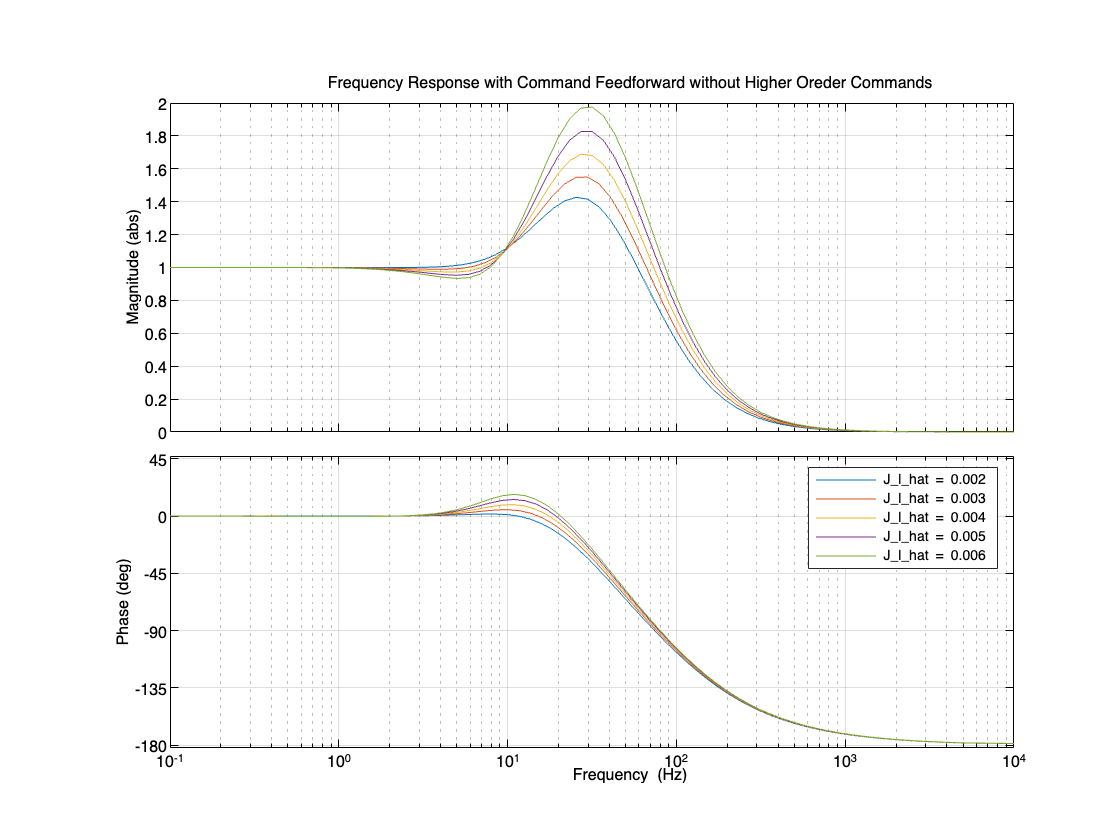


% TF plot with different J_l
opts = bodeoptions;
opts.MagUnits = 'abs';
opts.FreqUnits = 'Hz';
opts.Grid = 'on';
opts.XLimMode = 'manual';
opts.XLim = [0.1,1e+4];

n = 1;
tfs_b = {5};

figure
for x = linspace(2e-3, 6e-3, 5)
    EQ3_b_tf = subs(EQ3_b,J_hat_l,x);
    tfs_b{n} = syms2tf(simplify(rhs(EQ3_b_tf)));

    hold on;
    bodeplot(tfs_b{n},opts);
    n = n+1;
end
hold off;

legend('J_l_hat = 0.002','J_l_hat = 0.003','J_l_hat = 0.004','J_l_hat = 0.005','J_l_hat = 0.006')
title('Frequency Response with Command Feedforward without Higher Oreder Commands')

## c) State Tracking Filter

syms K_0 K_1 K_2 tau_1 tau_2 tau_3
syms theta_ast theta_ast_mod omega_ast_mod omega_dot_ast_mod

% Find the Value of K
eq1_c = (s + tau_1) * (s + tau_2) * (s + tau_3)

$$eq1\_c = \left(s+\tau_{1}\right)\,\left(s+\tau_{2}\right)\,\left(s+\tau_{3}\right)$$

eq2_c = collect(eq1_c, s)

$$eq2\_c = s^{3}+\left(\tau_{1}+\tau_{2}+\tau_{3}\right)\,s^{2}+\left(\tau_{3}\,\left(\tau_{1}+\tau_{2}\right)+\tau_{1}\,\tau_{2}\right)\,s+\tau_{1}\,\tau_{2}\,\tau_{3}$$

subs1_c = coeffs(eq2_c,s);

K_0 = subs1_c(3)

$$K\_0 = \tau_{1}+\tau_{2}+\tau_{3}$$

K_1 = subs1_c(2)

$$K\_1 = \tau_{3}\,\left(\tau_{1}+\tau_{2}\right)+\tau_{1}\,\tau_{2}$$

K_2 = subs1_c(1)

$$K\_2 = \tau_{1}\,\tau_{2}\,\tau_{3}$$


eq3_c = omega_dot_ast_mod == (K_2/s + K_1 + s*K_0) * (theta_ast - theta_ast_mod)

$$eq3\_c = {{\dot{\omega }}^{*}}_{\mathrm{mod}}=\left(\theta^{*}-{\theta^{*}}_{\mathrm{mod}}\right)\,\left(\tau_{3}\,\left(\tau_{1}+\tau_{2}\right)+\tau_{1}\,\tau_{2}+s\,\left(\tau_{1}+\tau_{2}+\tau_{3}\right)+\frac{\tau_{1}\,\tau_{2}\,\tau_{3}}{s}\right)$$

eq4_c = omega_dot_ast_mod/s == omega_ast_mod

$$eq4\_c = \frac{{{\dot{\omega }}^{*}}_{\mathrm{mod}}}{s}={\omega^{*}}_{\mathrm{mod}}$$

eq5_c = omega_ast_mod/s == theta_ast_mod

$$eq5\_c = \frac{{\omega^{*}}_{\mathrm{mod}}}{s}={\theta^{*}}_{\mathrm{mod}}$$


S_c = solve([eq3_c,eq4_c,eq5_c], [theta_ast_mod omega_ast_mod omega_dot_ast_mod])

S_c = struct with fields:
        theta_ast_mod: (theta_ast*(s^2*tau_1 + s^2*tau_2 + s^2*tau_3 + s*tau_1*tau_2 + s*tau_1*tau_3 + s*tau_2*tau_3 + tau_1*tau_2*tau_3))/(s^2*tau_1 + s^2*tau_2 + s^2*tau_3 + s^3 + s*tau_1*tau_2 + s*tau_1*tau_3 + s*tau_2*tau_3 + tau_1*tau_2*tau_3)
        omega_ast_mod: (s*theta_ast*(s^2*tau_1 + s^2*tau_2 + s^2*tau_3 + s*tau_1*tau_2 + s*tau_1*tau_3 + s*tau_2*tau_3 + tau_1*tau_2*tau_3))/(s^2*tau_1 + s^2*tau_2 + s^2*tau_3 + s^3 + s*tau_1*tau_2 + s*tau_1*tau_3 + s*tau_2*tau_3 + tau_1*tau_2*tau_3)
    omega_dot_ast_mod: (s^2*theta_ast*(s^2*tau_1 + s^2*tau_2 + s^2*tau_3 + s*tau_1*tau_2 + s*tau_1*tau_3 + s*tau_2*tau_3 + tau_1*tau_2*tau_3))/(s^2*tau_1 + s^2*tau_2 + s^2*tau_3 + s^3 + s*tau_1*tau_2 + s*tau_1*tau_3 + s*tau_2*tau_3 + tau_1*tau_2*tau_3)



EQ1_c = theta_ast_mod == S_c.theta_ast_mod

$$EQ1\_c = {\theta^{*}}_{\mathrm{mod}}=\frac{\theta^{*}\,\left(s^{2}\,\tau_{1}+s^{2}\,\tau_{2}+s^{2}\,\tau_{3}+s\,\tau_{1}\,\tau_{2}+s\,\tau_{1}\,\tau_{3}+s\,\tau_{2}\,\tau_{3}+\tau_{1}\,\tau_{2}\,\tau_{3}\right)}{s^{2}\,\tau_{1}+s^{2}\,\tau_{2}+s^{2}\,\tau_{3}+s^{3}+s\,\tau_{1}\,\tau_{2}+s\,\tau_{1}\,\tau_{3}+s\,\tau_{2}\,\tau_{3}+\tau_{1}\,\tau_{2}\,\tau_{3}}$$

EQ2_c = EQ1_c/theta_ast

$$EQ2\_c = \frac{{\theta^{*}}_{\mathrm{mod}}}{\theta^{*}}=\frac{s^{2}\,\tau_{1}+s^{2}\,\tau_{2}+s^{2}\,\tau_{3}+s\,\tau_{1}\,\tau_{2}+s\,\tau_{1}\,\tau_{3}+s\,\tau_{2}\,\tau_{3}+\tau_{1}\,\tau_{2}\,\tau_{3}}{s^{2}\,\tau_{1}+s^{2}\,\tau_{2}+s^{2}\,\tau_{3}+s^{3}+s\,\tau_{1}\,\tau_{2}+s\,\tau_{1}\,\tau_{3}+s\,\tau_{2}\,\tau_{3}+\tau_{1}\,\tau_{2}\,\tau_{3}}$$


tau_1 = 2*pi*10;
tau_2 = 2*pi*100;
tau_3 = 2*pi*1000;

% Transfer Function
EQ3_c = subs(EQ2_c)

$$EQ3\_c = \frac{{\theta^{*}}_{\mathrm{mod}}}{\theta^{*}}=\frac{2220\,\pi \,s^{2}+444000\,\pi^{2}\,s+8000000\,\pi^{3}}{s^{3}+2220\,\pi \,s^{2}+444000\,\pi^{2}\,s+8000000\,\pi^{3}}$$

tf1_c = syms2tf(rhs(EQ3_c));

% Sinusoidal Response at different frequency
fr = 10

fr = 10

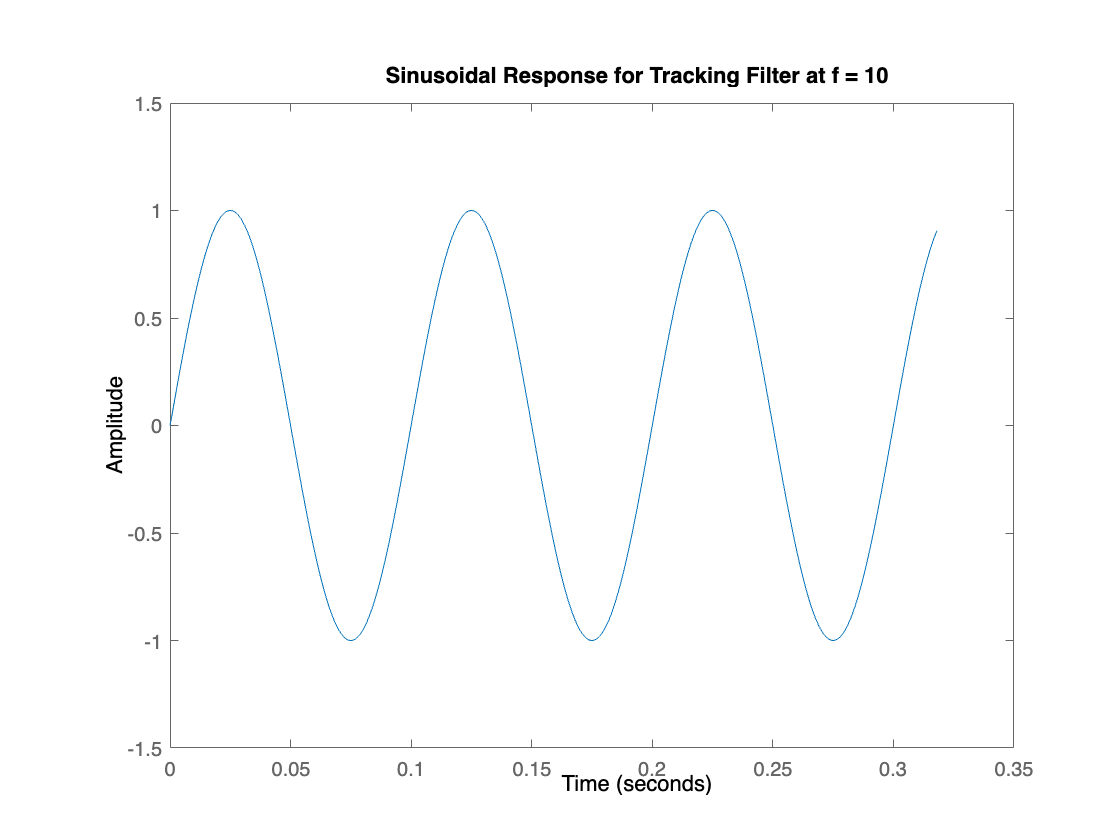

t = 0:0.01/fr:10/(pi*fr);
u = sin(fr*2*pi*t);
lsim(tf1_c,u,t)
title('Sinusoidal Response for Tracking Filter at f = 10')


fr = 100

fr = 100

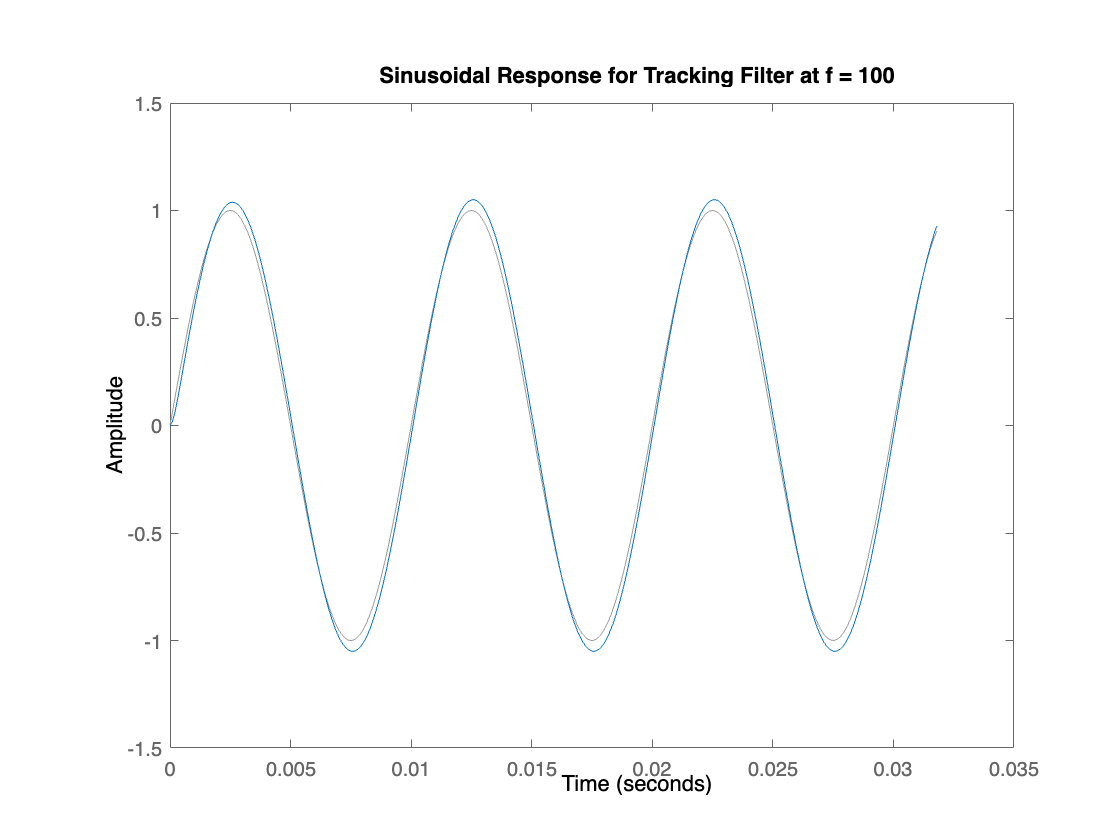

t = 0:0.01/fr:10/(pi*fr);
u = sin(fr*2*pi*t);
lsim(tf1_c,u,t)
title('Sinusoidal Response for Tracking Filter at f = 100')


fr = 1000

fr = 1000

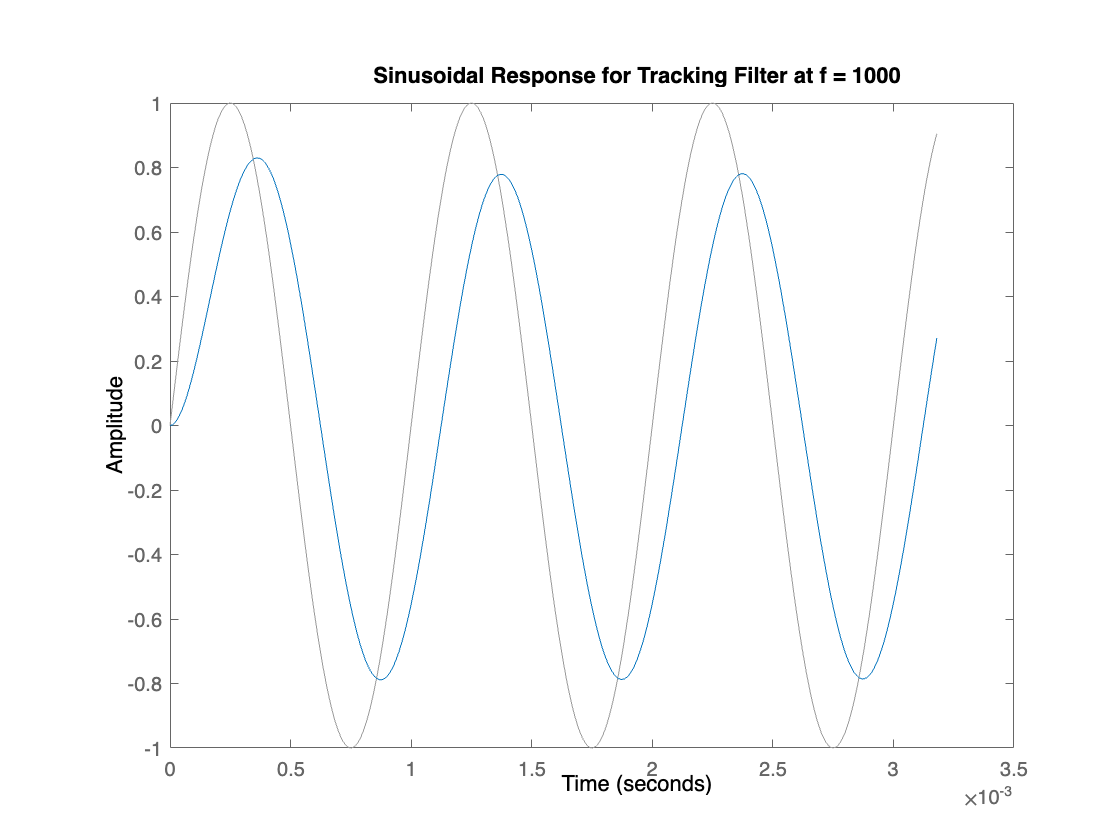

t = 0:0.01/fr:10/(pi*fr);
u = sin(fr*2*pi*t);
lsim(tf1_c,u,t)
title('Sinusoidal Response for Tracking Filter at f = 1000')

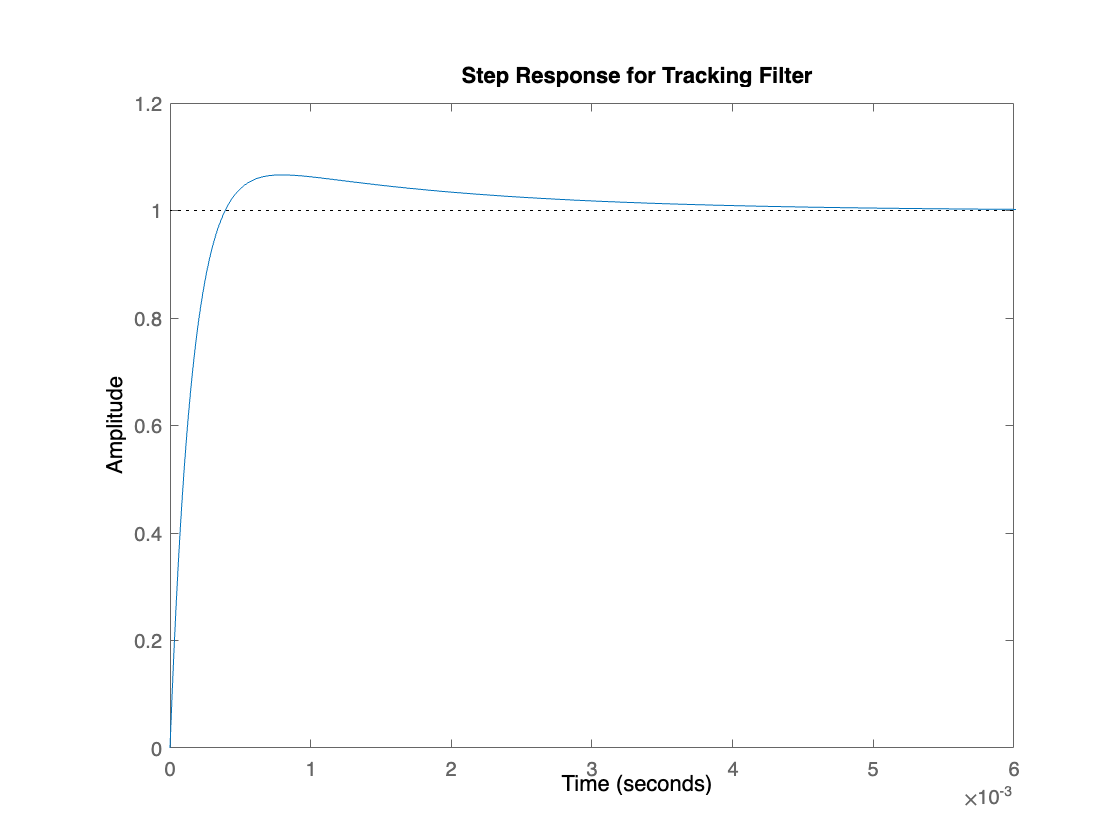


% step response
step(tf1_c)
title('Step Response for Tracking Filter')

## d) Frequency Response w/ Command Feedforward and State Tracking Filter w/o Higher Oreder Commands

% For part b
EQ3_b

$$EQ3\_b = \frac{\theta_{l}}{{\theta^{*}}_{l}}=\frac{\left(250000000\,{\hat{J}}_{l}+1502425\right)\,s^{3}+242594150\,s^{2}+9415502025\,s+50202500000}{6\,s^{5}+6390\,s^{4}+2002425\,s^{3}+242594150\,s^{2}+9415502025\,s+50202500000}$$


% For part c
EQ3_c

$$EQ3\_c = \frac{{\theta^{*}}_{\mathrm{mod}}}{\theta^{*}}=\frac{2220\,\pi \,s^{2}+444000\,\pi^{2}\,s+8000000\,\pi^{3}}{s^{3}+2220\,\pi \,s^{2}+444000\,\pi^{2}\,s+8000000\,\pi^{3}}$$


% The output of State Tracking Filter in part c is the command input of
% system in part b, therefore the complete transfer response is
EQ1_d = theta_l/theta_ast == rhs(EQ3_b)*rhs(EQ3_c)

$$EQ1\_d = \begin{array}{l} \frac{\theta_{l}}{\theta^{*}}=\frac{\left(\sigma_{2}+\sigma_{1}+8000000\,\pi^{3}\right)\,\left(\left(250000000\,{\hat{J}}_{l}+1502425\right)\,s^{3}+242594150\,s^{2}+9415502025\,s+50202500000\right)}{\left(s^{3}+\sigma_{2}+\sigma_{1}+8000000\,\pi^{3}\right)\,\left(6\,s^{5}+6390\,s^{4}+2002425\,s^{3}+242594150\,s^{2}+9415502025\,s+50202500000\right)}\\ \mathrm{where}\\ \sigma_{1}=444000\,\pi^{2}\,s\\ \sigma_{2}=2220\,\pi \,s^{2} \end{array}$$

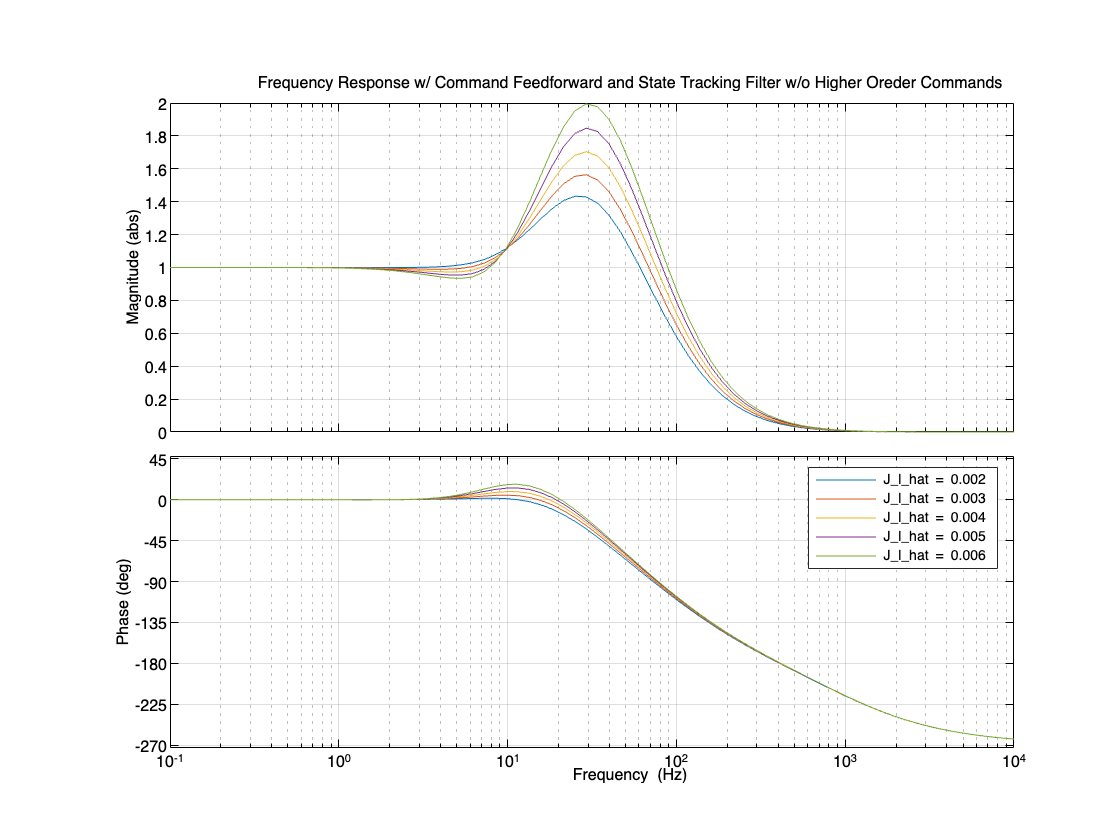


n = 1;
tfs_d = {5};

figure
for x = linspace(2e-3, 6e-3, 5)
    EQ1_d_tf = subs(EQ1_d,J_hat_l,x);
    tfs_d{n} = syms2tf(simplify(rhs(EQ1_d_tf)));

    hold on;
    bodeplot(tfs_d{n},opts);
    n = n+1;
end
hold off;

legend('J_l_hat = 0.002','J_l_hat = 0.003','J_l_hat = 0.004','J_l_hat = 0.005','J_l_hat = 0.006')
title('Frequency Response w/ Command Feedforward and State Tracking Filter w/o Higher Oreder Commands')